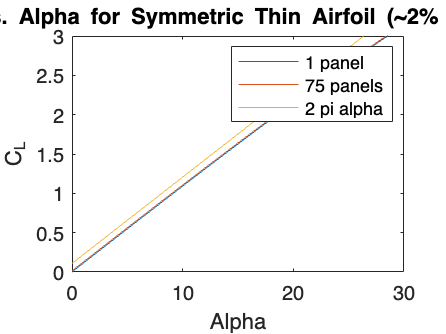

N = 10

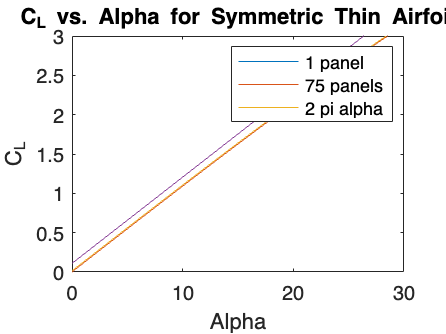

clear all

close all
clc

% Problem 1
for alpha=1:31

    [~,C_l,~,~,~,~,~,~] = computePanelData(10,-1000,alpha-1,1,1);
    Cl_1_panel(alpha)=C_l;

    [~,C_l,~,~,~,~,~,~] = computePanelData(10,-1000,alpha-1,75,1);
    Cl_75_panel(alpha)=C_l;

    Cl_eqn(alpha)= 2*pi*(alpha*(pi/180));

end

% Problem 2

for a=1:31

    [~,C_l,~,~,~,~,~,~] = computePanelData(10,-62,alpha-1,1,1);
    Cl_1_panel(alpha)=C_l;

    [~,C_l,~,~,~,~,~,~] = computePanelData(10,-62,alpha-1,75,1);
    Cl_75_panel(alpha)=C_l;

    Cl_eqn(alpha)= 2*pi*(alpha*(pi/180));

end

alpha = linspace(0,30,31);

Cl_combined = [Cl_1_panel; Cl_75_panel; Cl_eqn];

plot(alpha,Cl_combined);
title('C_L vs. Alpha for Symmetric Thin Airfoil (~2% camber)')
xlabel('Alpha')
ylabel('C_L')
legend('1 panel', '75 panels', '2 pi alpha')
ylim([0,3])
xlim([0,30])

% Problem 3 

[gamma,~,~,~,~,~,~,~] = computePanelData(10,-1000,5,75,1);

circulation = sum(gamma)

circulation = 28.1533

circulation_eqn = 10*10*pi*5*(pi/180)

circulation_eqn = 27.4156

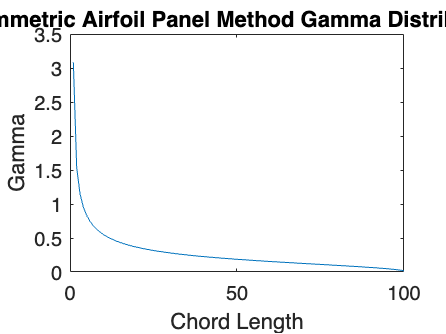

% Problem 4

[gamma,~,camber,~,~,~,~,~] = computePanelData(10,-1000,5,100,1);
length = linspace(1,length(gamma),length(gamma));
plot(length,gamma)
title('Symmetric Airfoil Panel Method Gamma Distribution');
xlabel('Chord Length');
ylabel('Gamma');

% Problem 5

N = 10

% Upstream airfoil
xi_u = 0;
yi_u = 0;
xf_u = 1.494;
yf_u = -0.1307;

% Downstream airfoil
xi_d = 1.624;
yi_d = -0.1327;
xf_d = 3.109;
yf_d = -0.3415;

%Length_u = sqrt((xf_u-xi_u)^2+(yf_u-yi_u)^2)
%Length_d = sqrt((xf_d-xi_d)^2+(yf_d-yi_d)^2)

% Points for the upstream airfoil
x_u = linspace(xi_u,xf_u,N+1);
y_u = linspace(yi_u,yf_u,N+1);
plot(x_u,y_u);

hold on

% Points for the downstream airfoil
x_d = linspace(xi_d,xf_d,N+1);
y_d = linspace(yi_d,yf_d,N+1);
plot(x_d,y_d);

% creating the panels
            
                PCoords_g = zeros(N,4); 
                PCoords_g_u = zeros(N,4); 
                PCoords_g_d = zeros(N,4); 


                for e=1:N
                        
                    PCoords_g_u(e, 1) = x_u(e);
                    PCoords_g_u(e, 2) = y_u(e);
                    PCoords_g_u(e, 3) = x_u(e+1);
                    PCoords_g_u(e, 4) = y_u(e+1);

                end


                for e=1:N
                        
                    PCoords_g_d(e, 1) = x_d(e);
                    PCoords_g_d(e, 2) = y_d(e);
                    PCoords_g_d(e, 3) = x_d(e+1);
                    PCoords_g_d(e, 4) = y_d(e+1);

alpha = linspace(0,30,31);

Cl_combined = [Cl_1_panel; Cl_75_panel; Cl_eqn];

plot(alpha,Cl_combined);
title('C_L vs. Alpha for Symmetric Thin Airfoil')
xlabel('Alpha')
ylabel('C_L')
legend('1 panel', '75 panels', '2 pi alpha')
ylim([0,3])
xlim([0,30])

                end
                
                PCoords_g =[PCoords_g_u; PCoords_g_d];


% panel length

                L = 1.5/N;

% calculate the normal and tangential vectors

% x_g = zeros(N,2);
%                 for e=1:N
%                     x_g(e,1) = (PCoords_g(e,3)-PCoords_g(e,1))/L(e); %i_hat
%                     x_g(e,2) = (PCoords_g(e,4)-PCoords_g(e,2))/L(e); %j_hat
%                 end
% 
%                 y_g = zeros(N,2);
%                 y_g = [0 1; -1 0]*transpose(x_g);
%                 y_g = -transpose(y_g);



